# Code to analyze the motion of a ball thrown on a merry-go-round

Group member #1 name: Caiden Bonney

Section: **FILL_IN_HERE**

This is a visualization of translational motion on a rotating body, which will induce the Coriolis effect. We will study the motion of a ball, thrown by a person (A), which will end up being caught by person (B),

The following representations are made for the simulation:

- Person (A) is represented by a blue star (*).

- Person (B) is represented by a black cross (x).  

- The ball is represented by a red circle (o).

- The fixed coordinate system $XY(Z)$ is represented by black axes.

- The rotating coordinate system $xy(z)$ is represented by blue axes.

## Setup

close all
clear
clc

w = -0.739 %angular velocity of the merry-go-round

w = -0.7390

t_final = 1 %time the simulation ends

t_final = 1

R = 1 %radius of the merry-go-round

R = 1

v_throw = 1.673 %throw speed relative to the merry-go-round

v_throw = 1.6730

### Part 2A Analysis in the Fixed Frame

Studying the motion of the ball as seen by a stationary observer (bird-eye view).

theta = w*t_final;

v_Ball = [v_throw;0;0] + cross([0;0;w],[-R;0;0]);

dt = 0.010; %integration time step
t = 0:dt:t_final; %time array

X(1) = -R %initial position of the ball in the x direction

X = -1

Y(1) = 0 %initial position of the ball in the y direction

Y = 0

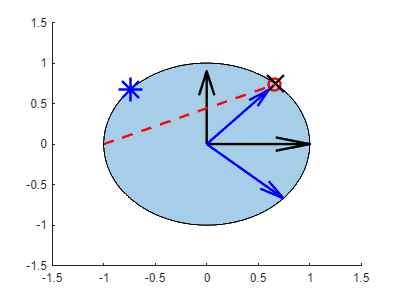


Disk = nsidedpoly(1000, 'Center', [0 0], 'Radius', R); %Ask MATLAB create a Polyshape
%this can be plotted to draw a disk (the merry-go-round).

%How to animate on MATLAB:

%Simply plot within a loop

%Use command 'pause(time)' to pause for 'time' seconds

%If you want to draw multiple things at once 'hold on' so that MATLAB keeps
%everything in the plot

%If you want to draw something and erase everything else 'hold off' then
%plot whatever you want

for i = 1:length(t)-1
    figure (1)
    plot(Disk)
    hold on
    
    %the instance t(i). Make sure this quantity is a 3x1 vector.

    %recommendation: for simplicity, apply Euler forward integration in
    %vector form like shown below:

    position = [X(i);Y(i);0] + dt*v_Ball; %notice that ignoring air resistance and gravity
    %means that z is constant and we dont care about it. (height of ball)

    X(i+1) = position(1,1);
    Y(i+1) = position(2,1);

    %%Indicate the location of each person (person A and person B) as
    %%measured by the fixed frame at this time step:

    theta = w*t(i);

    B_position = RotationMatrix(-theta)*[0;R;0];
    A_position = RotationMatrix(-theta)*[-R;0;0];
    
    YB = B_position(2,1);
    XB = B_position(1,1);
    XA = A_position(1,1);
    YA = A_position(2,1);
    %%

    plot(X(i),Y(i),'ro',MarkerSize=10,LineWidth=2) %plot where the ball is at this moment
    plot(XB,YB,'kx',MarkerSize=20,LineWidth=2) %plot where person B is at this moment
    plot(XA,YA,'b*',MarkerSize=20,LineWidth=2) %plot where person A is at this moment

    DrawCoordinateSystem(R,0,'k'); %make a plot of the X and Y axes at this time. The plot must represent
    %two vectors (including vector arrows) with black color and line width
    %of 2. Use the DrawCoordinateSystem function

    DrawCoordinateSystem(R,theta,'b'); %make a plot of the x and y axes at this time. The plot must represent
    %two vectors (including vector arrows) with blue color and line width
    %of 2. Use the DrawCoordinateSystem function
    
    % plot(X,Y,'r--',LineWidth=2) % plots the trajectory of the ball during movement
    
    pause(0.01) %update plot every 100 ms (if possible)
    hold off %I'm holding off here so that, once the next loop starts,
    %I erase everything from this loop from my plot.
end

%Plot the total trajectory of the ball below on the same figure once the
%loop concludes:

hold on
plot(X,Y,'r--',LineWidth=2)
hold off

## Part 2B Analysis in the Rotating Frame - Method 1

Here, we study the motion of the ball from the perspective of an observer rotating with the the merry-go-round.

For the first study, we simply find the location of the ball as a function of time by utilizing our results for X(t) and Y(t) from the part A and multiplying these results by a rotation matrix representing the angle of rotation of the merry-go-round frame xyz relative to the fixed frame XYZ at each time step. (no integration is needed in this part).

for i=1:length(x)-1
    figure(2)
    theta = FILL_IN_HERE %find an expression for theta(t)

    position_rotating = FILL_IN_HERE %find the position of the ball (as a vector) at this moment
    %use what you have learned about rotation matrices to your advantage.
    %Use the RotationMatrix function

    x_rotating(i) = FILL_IN_HERE %position in the x direction at this moment
    y_rotating(i) = FILL_IN_HERE %position in the y direction at this moment
    
    %Indicate the locations of person A and B as measured by the rotating
    %frame

    xA_rotating = FILL_IN_HERE
    yA_rotating = FILL_IN_HERE
    xB_rotating = FILL_IN_HERE
    yB_rotating = FILL_IN_HERE

    plot(Disk)
    hold on
    plot(x_rotating(i),y_rotating(i),'ro',MarkerSize=10,LineWidth=2)
    plot(xA_rotating,yA_rotating,'b*',MarkerSize=20,LineWidth=2)
    plot(xB_rotating,yB_rotating,'kx',MarkerSize=20,LineWidth=2)

    FILL_IN_HERE
    DrawCoordinateSystem()%make a plot of the X and Y axes at this time. The plot must represent
    %two vectors (including vector arrows) with black color and line width
    %of 2

    FILL_IN_HERE %make a plot of the x and y axes at this time. The plot must represent
    %two vectors (including vector arrows) with blue color and line width
    %of 2
    pause(0.01)
    hold off
end

Unrecognized function or variable 'x'.


%Plot the total trajectory of the ball below on the same figure once the
%loop concludes:
hold on
plot(x_rotating,y_rotating,'r--',LineWidth=2)
hold off

## Part 2B Analysis in the Rotating Frame - Method 2

Here, we study the motion of the ball from the perspective of an observer rotating with the the merry-go-round.

For this study, we will do the entire analysis of motion i.e, going from velocity to position of the ball in the rotating frame. Thus, we do the integration much like we have done in part A, but in the rotating frame instead here. The analysis is more complicated here than B. Part 1, but it yields the same reults.

x(1) = -R; %position of the ball as measured in the rotating frame initially in x
y(1) = 0; %position of the ball as measured in the rotating frame initially in y

FILL_IN_HERE
%you will have to write a loop, much like in Part A to compute the position
%of the ball through numerical integration and animate the motion of the
%ball.
%In this case, velocity and position are both measured using axes that move
%so think carefully about how to interpret the motion of the ball.

%SMALL TIP:

%Do you notice that you are doing some computation over and over again?
%consider writing a function that you can call to do this computation for
%you.
function Rot = RotationMatrix(theta)
    Rot = [cos(theta) sin(theta) 0; -sin(theta) cos(theta) 0; 0 0 1];
end

function Result = DrawCoordinateSystem(Length, Angle, Color)
%x axis
    quiver(0, 0, Length*cos(Angle), Length*sin(Angle), 0, 'LineWidth', 2, 'MaxHeadSize', 1, 'Color', Color);
%y axis
    quiver(0, 0, Length*cos(Angle+pi()/2), Length*sin(Angle+pi()/2), 'LineWidth', 2, 'MaxHeadSize', 1, 'Color', Color);
end